# Markov process

## Clean variables

clc, clear all, close all;
syms y_o z_o x_o v_o w_o k;
syms s;

## Generamos la matrix de markov

A = [0,1/2,1/3,1,0;...
     1,0,1/3,0,1/3;...
     0,1/2,0,0,1/3;...
     0,0,0,0,1/3;...
     0,0,1/3,0,0];
 u = [x_o;y_o;z_o;v_o;w_o]

$$u = \left(\begin{array}{c} x_{o}\\ y_{o}\\ z_{o}\\ v_{o}\\ w_{o} \end{array}\right)$$

 [Vectors,values] = eig(A)

Vectors =   -0.5416 + 0.0000i  -0.3290 + 0.2109i  -0.3290 - 0.2109i  -0.2049 - 0.3645i  -0.2049 + 0.3645i
  -0.7221 + 0.0000i   0.6711 + 0.0000i   0.6711 + 0.0000i  -0.5188 + 0.0000i  -0.5188 + 0.0000i
  -0.4062 + 0.0000i  -0.4653 - 0.3074i  -0.4653 + 0.3074i  -0.0015 + 0.4335i  -0.0015 - 0.4335i
  -0.0451 + 0.0000i  -0.0244 - 0.1232i  -0.0244 + 0.1232i   0.3393 - 0.2601i   0.3393 + 0.2601i
  -0.1354 + 0.0000i   0.1475 + 0.2198i   0.1475 - 0.2198i   0.3858 + 0.1911i   0.3858 - 0.1911i


values =    1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.6480 + 0.2707i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.6480 - 0.2707i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.1480 + 0.3012i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.1480 - 0.3012i


 aux_det = det(A-s*eye(5))

$$aux\_det = -s^{5}+\frac{7\,s^{3}}{9}+\frac{2\,s^{2}}{9}-\frac{s}{18}+\frac{1}{18}$$

 solve(aux_det,s)

$$ans = \begin{array}{l} \left(\begin{array}{c} 1\\ \mathrm{root}\left(\sigma_{1},z,1\right)\\ \mathrm{root}\left(\sigma_{1},z,2\right)\\ \mathrm{root}\left(\sigma_{1},z,3\right)\\ \mathrm{root}\left(\sigma_{1},z,4\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=z^{4}+z^{3}+\frac{2\,z^{2}}{9}+\frac{1}{18} \end{array}$$

 A-eye(5)

ans =    -1.0000    0.5000    0.3333    1.0000         0
    1.0000   -1.0000    0.3333         0    0.3333
         0    0.5000   -1.0000         0    0.3333
         0         0         0   -1.0000    0.3333
         0         0    0.3333         0   -1.0000


## Descomposicion Jordan

[V,J] = jordan(A)

V =    4.0000 + 0.0000i  -0.0311 + 1.4760i  -0.0311 - 1.4760i  -0.8023 - 0.5473i  -0.8023 + 0.5473i
   5.3333 + 0.0000i   1.4130 - 2.1052i   1.4130 + 2.1052i  -1.0797 + 0.5350i  -1.0797 - 0.5350i
   3.0000 + 0.0000i  -1.9440 + 0.8122i  -1.9440 - 0.8122i   0.4440 + 0.9037i   0.4440 - 0.9037i
   0.3333 + 0.0000i  -0.4380 - 0.1830i  -0.4380 + 0.1830i   0.4380 - 0.8914i   0.4380 + 0.8914i
   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i


J =    1.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.6480 + 0.2707i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.6480 - 0.2707i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.1480 + 0.3012i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.1480 - 0.3012i


V_1 = inv(V)

V_1 =    0.0732 + 0.0000i   0.0732 + 0.0000i   0.0732 - 0.0000i   0.0732 - 0.0000i   0.0732 - 0.0000i
   0.0571 - 0.1556i   0.0051 + 0.1163i  -0.1267 + 0.0077i  -0.1605 + 0.1731i   0.1779 - 0.0785i
   0.0571 + 0.1556i   0.0051 - 0.1163i  -0.1267 - 0.0077i  -0.1605 - 0.1731i   0.1779 + 0.0785i
  -0.0937 + 0.0924i  -0.0417 - 0.0146i   0.0901 - 0.1218i   0.1239 + 0.3720i   0.2855 - 0.0504i
  -0.0937 - 0.0924i  -0.0417 + 0.0146i   0.0901 + 0.1218i   0.1239 - 0.3720i   0.2855 + 0.0504i



D_k = J^(k)

$$D\_k = \left(\begin{array}{ccccc} 1 & 0 & 0 & 0 & 0\\ 0 & {\left(-\frac{2918335244137535}{4503599627370496}+\frac{4876927967359973}{18014398509481984}\,\mathrm{i}\right)}^{k} & 0 & 0 & 0\\ 0 & 0 & {\left(-\frac{2918335244137535}{4503599627370496}-\frac{4876927967359973}{18014398509481984}\,\mathrm{i}\right)}^{k} & 0 & 0\\ 0 & 0 & 0 & {\left(\frac{2666141721809147}{18014398509481984}+\frac{5426484327247411}{18014398509481984}\,\mathrm{i}\right)}^{k} & 0\\ 0 & 0 & 0 & 0 & {\left(\frac{2666141721809147}{18014398509481984}-\frac{5426484327247411}{18014398509481984}\,\mathrm{i}\right)}^{k} \end{array}\right)$$

entrada = V_1*u


solucion = expand(V*D_k*entrada)

% 

% 

## Simulation syste

t = (0:0.1:15)

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000



U = [0.1;0.9;0;0;0];
% U = [ 0.2927
%     0.3902
%     0.2195
%     0.0244
%     0.0732];
Markov_matrix = [0,1/2,1/3,1,0;...
     1,0,1/3,0,1/3;...
     0,1/2,0,0,1/3;...
     0,0,0,0,1/3;...
     0,0,1/3,0,0];
Markov_matrix^(length(t))*U

ans =     0.2927
    0.3902
    0.2195
    0.0244
    0.0732


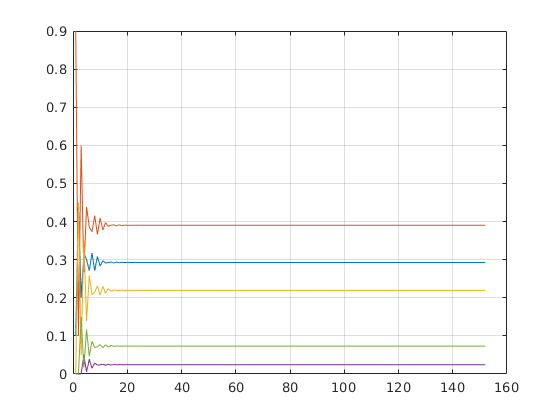

for k =1:length(t)
    U(:,k+1) = Markov_matrix*U(:,k); 
end
figure
plot(U(:,:)')
hold on;
grid on

## Solucion autovector


auto_vectores = V

auto_vectores =    4.0000 + 0.0000i  -0.0311 + 1.4760i  -0.0311 - 1.4760i  -0.8023 - 0.5473i  -0.8023 + 0.5473i
   5.3333 + 0.0000i   1.4130 - 2.1052i   1.4130 + 2.1052i  -1.0797 + 0.5350i  -1.0797 - 0.5350i
   3.0000 + 0.0000i  -1.9440 + 0.8122i  -1.9440 - 0.8122i   0.4440 + 0.9037i   0.4440 - 0.9037i
   0.3333 + 0.0000i  -0.4380 - 0.1830i  -0.4380 + 0.1830i   0.4380 - 0.8914i   0.4380 + 0.8914i
   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i


a_valores = inv(auto_vectores)*U(:,1)

a_valores =    0.0732 + 0.0000i
   0.0103 + 0.0891i
   0.0103 - 0.0891i
  -0.0469 - 0.0039i
  -0.0469 + 0.0039i


a_valores(1)*auto_vectores(:,1)

ans =    0.2927 + 0.0000i
   0.3902 + 0.0000i
   0.2195 + 0.0000i
   0.0244 + 0.0000i
   0.0732 + 0.0000i
